outdir = "./output/jobs/airborne_base";
rawdir = fullfile(outdir, "raw");
S = load(fullfile(rawdir, "baseline_pandemic_table.mat"));
pandemic_table = S.pandemic_table;
non_nan_table = pandemic_table(~isnan(pandemic_table.yr_start), :);

% Job config
job_config = yaml.loadFile(fullfile(outdir, "job_config.yaml"));
sim_periods = job_config.sim_periods; % draws per simulation run
num_simulations = job_config.num_simulations;
sim_num_list = 1:num_simulations;

ante_severity_matrix = zeros(num_simulations, sim_periods);
post_severity_matrix = zeros(num_simulations, sim_periods);

idx = sub2ind(size(ante_severity_matrix), non_nan_table.sim_num, non_nan_table.yr_start);
ante_severity_matrix(idx) = non_nan_table.eff_severity;
post_severity_matrix(idx) = non_nan_table.ex_post_severity;

B = 200;

grid_ante = [-Inf; unique(sort(ante_severity_matrix(:))); Inf];
grid_post = [-Inf; unique(sort(post_severity_matrix(:))); Inf];

B = 200;
boot_mat = zeros(B, length(grid_ante) - 1);

for b = 1:B
    b_sims = randsample(sim_num_list, num_simulations, true);

    ante_sev_b = ante_severity_matrix(b_sims, :);
    post_sev_b = post_severity_matrix(b_sims, :);

    ante_sev_b = sort(ante_sev_b(:));
    post_sev_b = sort(post_sev_b(:));

    S_ante_b = (numel(ante_sev_b) - histcounts(ante_sev_b, grid_ante, 'Normalization', 'cumcount')) / (numel(ante_sev_b) + 1);
    S_post_b = (numel(post_sev_b) - histcounts(post_sev_b, grid_ante, 'Normalization', 'cumcount')) / (numel(post_sev_b) + 1);


    boot_mat(b, :) = S_ante_b; 
end


ante_sev_b = sort(ante_sev_b(:));
post_sev_b = sort(post_sev_b(:));

temp = histcounts(ante_sev_b, grid_ante, 'Normalization', 'cumcount');
temp2 = cumsum(temp, 'reverse');

% Load Madhav data
madhav_exceedances = readtable("./data/clean/madhav_et_al_severity_exceedance.csv");

[madhav_severity_central, central_idx] = sort(madhav_exceedances.severity_central);
madhav_exceedance_central = madhav_exceedances.exceedance_central(central_idx);
[madhav_severity_upper, upper_idx] = sort(madhav_exceedances.severity_upper);
madhav_exceedance_upper = madhav_exceedances.exceedance_upper(upper_idx);
[madhav_severity_lower, lower_idx] = sort(madhav_exceedances.severity_lower);
madhav_exceedance_lower = madhav_exceedances.exceedance_lower(lower_idx);

% Restrict all lines to the minimum severity shown in our model
min_sev = max([min(ex_post_severity_sorted), min(ex_ante_severity_sorted), min(madhav_severity_central)]);

% Restrict ex_ante to >= min_sev
ex_ante_valid = ex_ante_severity_sorted >= min_sev;
ex_ante_severity_plot = ex_ante_severity_sorted(ex_ante_valid);
exceedance_ante_plot = exceedance_ante(ex_ante_valid);
ci_ante_plot = ci_ante(ex_ante_valid, :);

% Restrict ex_post to >= min_sev
ex_post_valid = ex_post_severity_sorted >= min_sev;
ex_post_severity_plot = ex_post_severity_sorted(ex_post_valid);
exceedance_post_plot = exceedance_post(ex_post_valid);
ci_post_plot = ci_post(ex_post_valid, :);

% Restrict Madhav data to >= min_sev
madhav_valid = madhav_severity_central >= min_sev;
madhav_severity_central_plot = madhav_severity_central(madhav_valid);
madhav_exceedance_central_plot = madhav_exceedance_central(madhav_valid) / 100;
madhav_exceedance_upper_plot = madhav_exceedance_upper(madhav_valid) / 100;
madhav_exceedance_lower_plot = madhav_exceedance_lower(madhav_valid) / 100;

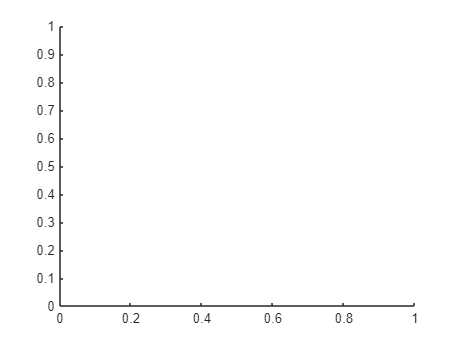

% Create figure with appropriate size and style
fig = figure('Position', [100 100 800 600]);
hold on;


% Colors
ex_ante_color = [0 0.4470 0.7410];
ex_post_color = [0.8500 0.3250 0.0980];
madhav_color = [0.4940 0.1840 0.5560];

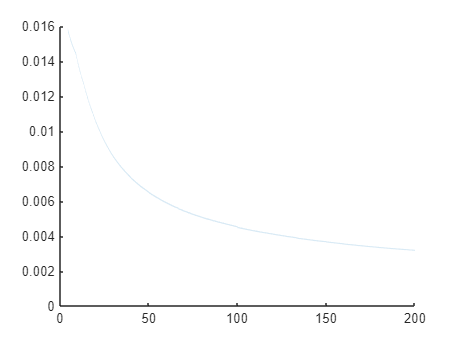

% Plot ex ante with 95% CI
fill([ex_ante_severity_plot; flipud(ex_ante_severity_plot)], ...
     [ci_ante_plot(:,1); flipud(ci_ante_plot(:,2))], ...
     ex_ante_color, 'FaceAlpha', 0.15, 'EdgeColor', 'none')

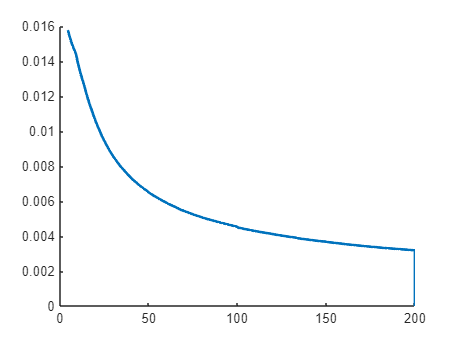

h_ante = plot(ex_ante_severity_plot, exceedance_ante_plot, 'LineWidth', 2, ...
    'Color', ex_ante_color, 'DisplayName', 'Our model (without vaccination)');